# findGeomLivescript                                                           

In this practicum we will calculate the geometry solution (P) for a camera using the correspondences between real world coordinates of ground control points (GCPs) and the digitized location of GCPs in an image. This demonstration requires nlinfit.m from  the Matlab Statistics and Machine Learning Toolbox.

clear

add UAV-Processing-Toolbox path so you can access makeLCPP3.m to save calibration parameters

addpath('../')
addpath('../neededCILRoutines')


## 1.  input info for Ground Control Point (GCP) and Lens Calibration  Parameter (LCP) and image data:

Define a "station" name

inputs.stationStr = 'Aerielle';


Choose the director that has demoGCPFile.mat (should be in the UAV-Processing-Toolbox)

gcpFileDir = uigetdir([],'Select directory that contains demoGCPFile.mat');
inputs.gcpFn = [gcpFileDir,filesep,'demoGCPFile.mat'];


Select an image for the demo (choose image 00001000.jpg in the geomDemo directory)

[imageFile,imagePath] = uigetfile('*','Select the image to use for geom demo');
inputs.Ifn = [imagePath,imageFile];


## 2.  Geometry solution Inputs:

The six extrinsic variables, the camera location and viewing angles in the order [ xCam yCam zCam Azimuth Tilt Roll]. Some may be known and some unknown.  Enter 1 in knownFlags for known variable.  For example, knownFlags = [1 1 0 0 0 1] means that camX and  camY and roll are known so should not be solved for. Enter values for all parameters below.  If the variable is known, the routine will use this data.  If not, this will be the seed for thenonlinear search. Try different guesses.


prompt = {['This vector defines the six extrinsic variables: the (x,y,z) camera ',...
    'location and the three viewing angles in the order [ xCam yCam zCam Azimuth',...
    'Tilt Roll]. Enter 1 in knownFlags for known variables and 0 for unkowns.  For example,',...
    'knownFlags = [1 1 0 0 0 1] means that camX and camY and roll are ',...
    'known so should not be solved for. knowFlags = '], 'Input (x,y) location of camera',...
    'Input elevation of camera','Input azimuth and tilt','Input roll'};
dlg_title = 'Extrinsic Inputs';
num_lines = 1;
defaultans = {'0 0 0 0 0 0','0 600','100','95 60','0'};
answer = inputdlg(prompt,dlg_title,num_lines,defaultans);

inputs.knownFlags = logical(str2num(cell2mat(answer(1))));
inputs.xyCam = str2num(cell2mat(answer(2)));
inputs.zCam = str2num(cell2mat(answer(3)));             % based on last data run                
inputs.azTilt = str2num(cell2mat(answer(4))) / 180*pi;          % first guess
inputs.roll = str2num(cell2mat(answer(5))) / 180*pi; 
betas = [inputs.xyCam inputs.zCam inputs.azTilt inputs.roll];  % fullvector
inputs.beta0 = betas(find(~inputs.knownFlags));
inputs.knowns = betas(find(inputs.knownFlags));

## Prepare to digitize GCPs

Examine your image and determine which GCPs can be seen and digitized.  List them in the order that you want to digitize them.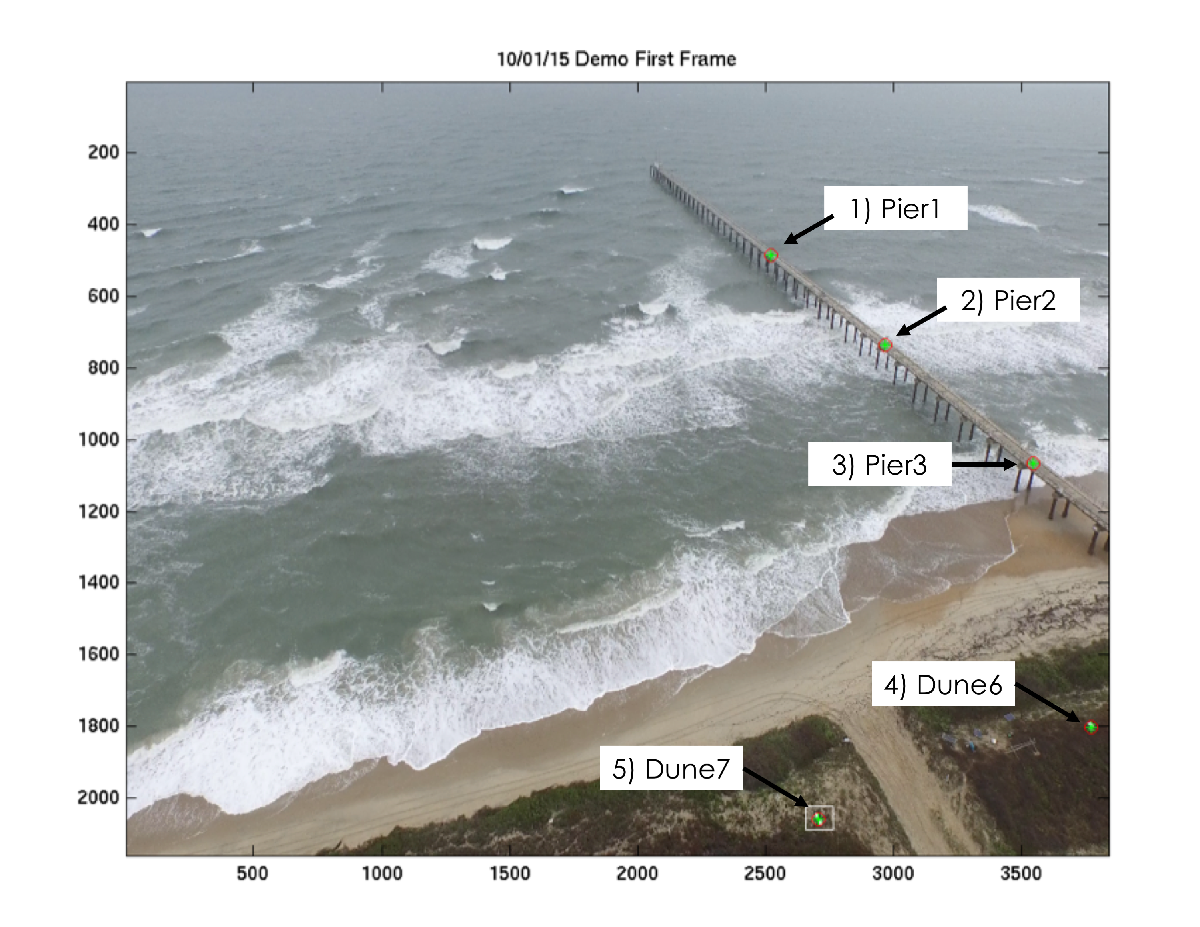

prompt = {'Examine your image and determine which GCPs can be seen and digitized.  List them in the order that you want to digitize them.'};
dlg_title = 'GCP Inputs';
num_lines = 1;
defaultans = {'1 2 3 6 7'};
answer = inputdlg(prompt,dlg_title,num_lines,defaultans);
inputs.gcpList = str2num(cell2mat(answer));      % use these gcps for init beta soln

% Because nlinfit requires globals, we set up a variable globals (under 
% metadata) that contains the lcp as well as the flags and values for
% known geometry variables (eg if we know the camera roll).  To minimize
% the use of globals we pass this explicitly except for nlinfit uses when
% we declare it to be global within the calling subroutine.
meta.globals.knownFlags = inputs.knownFlags;
meta.globals.knowns = inputs.knowns;   

% Now load the gcp, lcp and image data
load(inputs.gcpFn);             % load gcps
I = imread(inputs.Ifn);
[NV, NU, NC] = size(I);
meta.globals.lcp = makeLCPP3(inputs.stationStr,NU,NV);


## Digitize GCPs and solve for the geometry

find6DOFGeom.m calculates the non-linear fit using nlinfit.m and the function findUVnDOF.m. It returns the geometry (extrinsics)  [camera X, camera Y, camera Z, azimuth, tilt, roll]. NOTE:all angles are in radians in your local coordinate system. 

[beta, UV] = find6DOFGeom(I, gcp, inputs, meta);

computing geometry using 5 control points
Click anywhere on figure to begin
Zoom in to see pier1 then press Enter
Digitize pier1
Zoom in to see pier2 then press Enter
Digitize pier2
Zoom in to see pier3 then press Enter
Digitize pier3
Zoom in to see dune6 then press Enter
Digitize dune6
Zoom in to see dune7 then press Enter
Digitize dune7


## Display the result

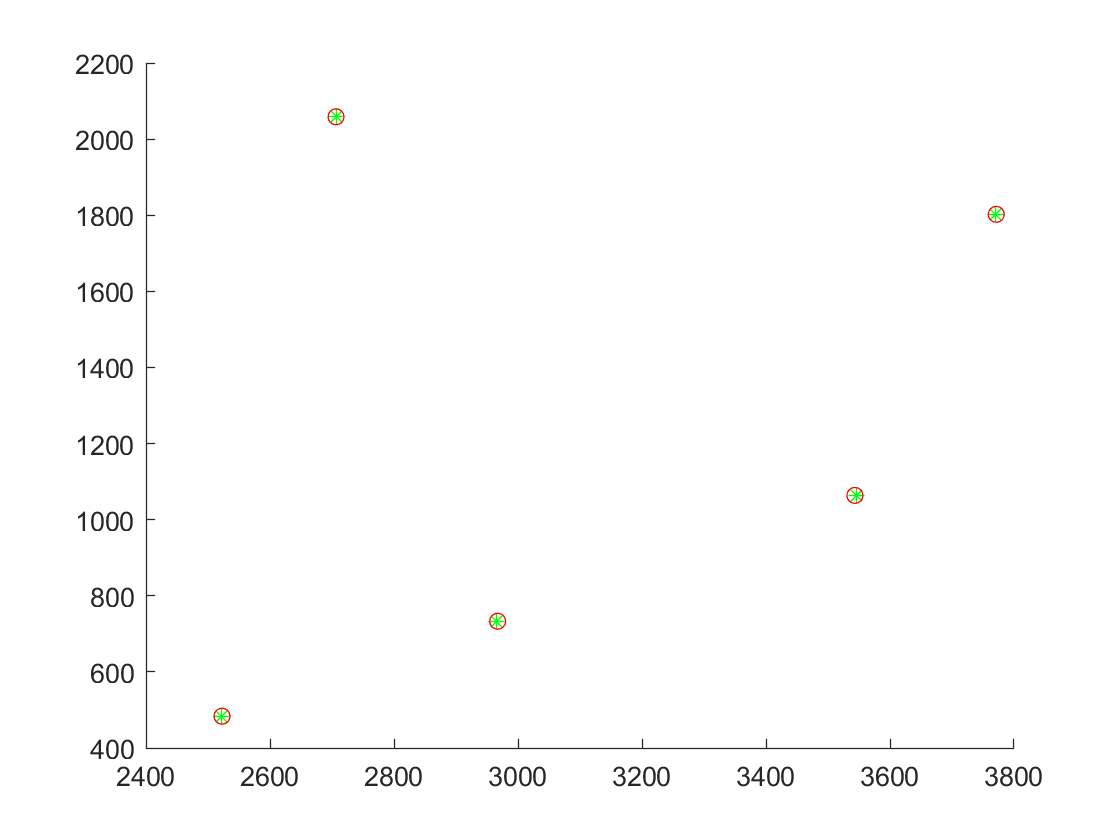

% display on image to see quality of fit
x = [gcp(inputs.gcpList).x];
y = [gcp(inputs.gcpList).y];
z = [gcp(inputs.gcpList).z];
xyz = [x' y' z'];
hold on
UV2 = findUVnDOF(beta,xyz,meta.globals);
UV2 = reshape(UV2,[],2);
plot(UV(:,1),UV(:,2),'g*')
plot(UV2(:,1),UV2(:,2),'ro')


% display text results cuz this is a demo.
display(['Camera position (x,y,z) is ' num2str(beta(1:3))])

Camera position (x,y,z) is 0.6565299      656.4854      79.16153


display(['Viewing angles (az, tilt, roll) are ' num2str(beta(4:6)*180/pi)])

Viewing angles (az, tilt, roll) are 100.6796      62.63805    0.09414951
